# **MATLAB基本操作**

## 更多信息参考 [MATLAB入门指南](matlab:open('C:\Users\16054\OneDrive\Desktop\灯りちゃん\数模\CUMCU\基本信息.docx'))

p = 500+3

p = 503

`点击实时编辑器的 文本`

此处可以插入图片、方程、代码...进行实时文字编辑

1+5

ans = 6

同时不影响代码的编辑，点一下实时编辑器的代码 又能写代码了

***注意，以上功能只限于实时脚本***

运行节分隔后，每一节运行与否互不干涉(不要f5，点运行节ctrl+enter

s= 1000+1

s = 1001

a=5+3 ;
a="ivbsdilurh"

a = "ivbsdilurh"

b="fbidvbdk""fd""frgvf"

b = "fbidvbdk"fd"frgvf"

c=a + "eeeeee" 

c = "ivbsdilurheeeeee"



DNA='GGTACTCA'

DNA = 'GGTACTCA'

s=DNA(4)

s = 'A'

DNA2=[DNA,'ATCG']

DNA2 = 'GGTACTCAATCG'

一些基本运算...

# **MATLAB矩阵运算**

创建一个1x6矩阵

a = [1 2 3 8 7 4]

a =      1     2     3     8     7     4


每个元素+3

b = a + 3

b =      4     5     6    11    10     7


**plot函数作图**，以索引为横坐标

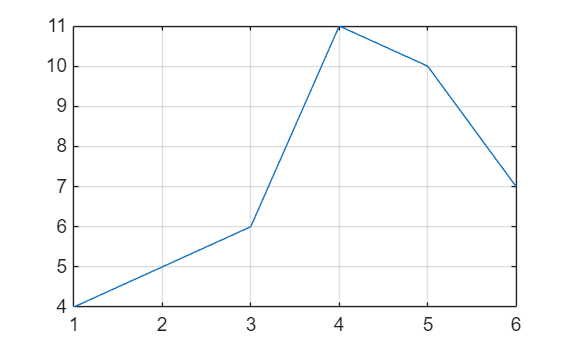

plot(b)
grid on

**多维矩阵**：空格or逗号来分隔每一行元素，分号分隔每行

常见运算：**转置、取逆、求特征值or特征向量**

A = [3 2 1;2 4 1;3 9 2]

A =      3     2     1
     2     4     1
     3     9     2


B = A'          %求转置

B =      3     2     3
     2     4     9
     1     1     2



[D,V] =  eig(A) %求特征向量和特征值

D =    -0.3534   -0.5691   -0.2508
   -0.4152    0.1144   -0.1181
   -0.8383    0.8143    0.9608


V =     7.7217         0         0
         0    1.1673         0
         0         0    0.1109


E = inv(A)      %求逆矩阵

E =    -1.0000    5.0000   -2.0000
   -1.0000    3.0000   -1.0000
    6.0000  -21.0000    8.0000


F =  A*E

F =     1.0000         0         0
    0.0000    1.0000         0
    0.0000         0    1.0000


**矩阵乘法，矩阵点乘（对应元素相乘）**

C = A*B

C =     14    15    29
    15    21    44
    29    44    94


E = A.*B        %对应元素相乘

E =      9     4     3
     4    16     9
     3     9     4


使用A**对方程A*x=b求解**，使用  \  运算符

即 **计算  A逆*b**

（谁在斜杠相对下面的位置谁就取逆矩阵）

b = [1;3;5]

b =      1
     3
     5


x = A\b

x =      4
     3
   -17


%验证
s = A*x - b

s =      0
     0
     0


如果**一个操作数是标量，而另一个不是**

则MATLAB会将该标量**隐式扩展**为与另一个操作数具有相同的的大小

H = [1 1 1;2 2 2;3 3 3]

H =      1     1     1
     2     2     2
     3     3     3


K = 4

K = 4

M = K + H      %运算时，K变为3x3矩阵，每个元素都为4

M =      5     5     5
     6     6     6
     7     7     7


**不同维度的行向量和列向量相加（不同维度扩展到相同维度）**

N = [1 2 3 4]  %补到3行，每行1234

N =      1     2     3     4


P = [5;6;7]    %补到4列，每列567

P =      5
     6
     7


Q = N + P

Q =      6     7     8     9
     7     8     9    10
     8     9    10    11


# **MATLAB的四种二维图**

## **1. 线图**

plot函数用来创建x值和y值的简单线图

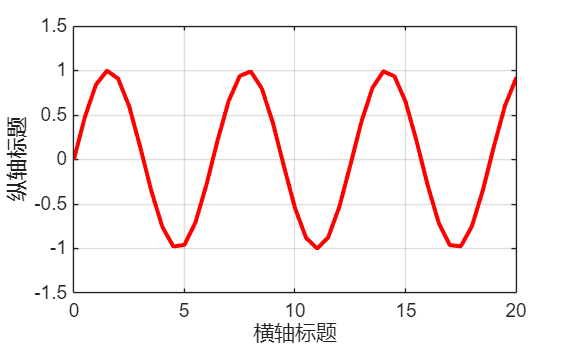

x = 0:0.5 :30 ;       %从0-30，每隔0.5取值一次（取点步长太大，可能图会很不顺滑，不精细）
y = sin(x) ;
plot(x,y,'LineWidth',2,'Color','red')        %若（x,y,'LineWidth,num)可加粗函数
axis([0 20 -1.5 1.5]) %调节范围              'Color','颜色’ 可以更改颜色
xlabel("横轴标题")
ylabel("纵轴标题")
grid on               %显示网格

多组函数显示在一张图

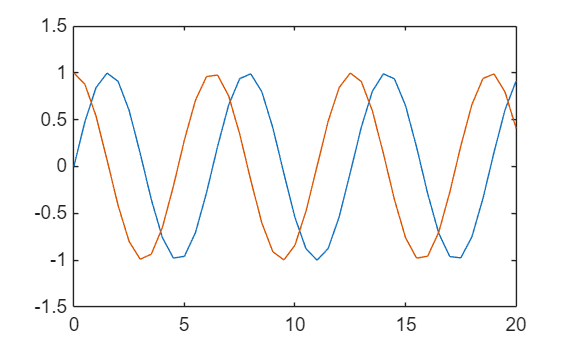

y1 = sin(x) ;
y2 = cos(x) ;
plot (x,y1,x,y2)
axis([0 20 -1.5 1.5])

## **2. 条形图**

**bar函数创建垂直条形图**

**barh函数创建水平条形图**

t = -3:0.5:3;
p = exp(-t.*t)   %t为向量要用点乘

p =     0.0001    0.0019    0.0183    0.1054    0.3679    0.7788    1.0000    0.7788    0.3679    0.1054    0.0183    0.0019    0.0001


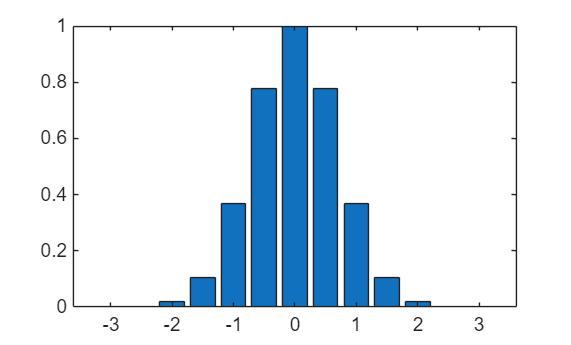

bar(t,p)

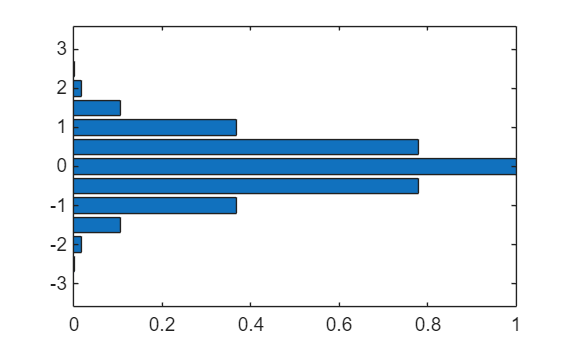

barh(t,p)

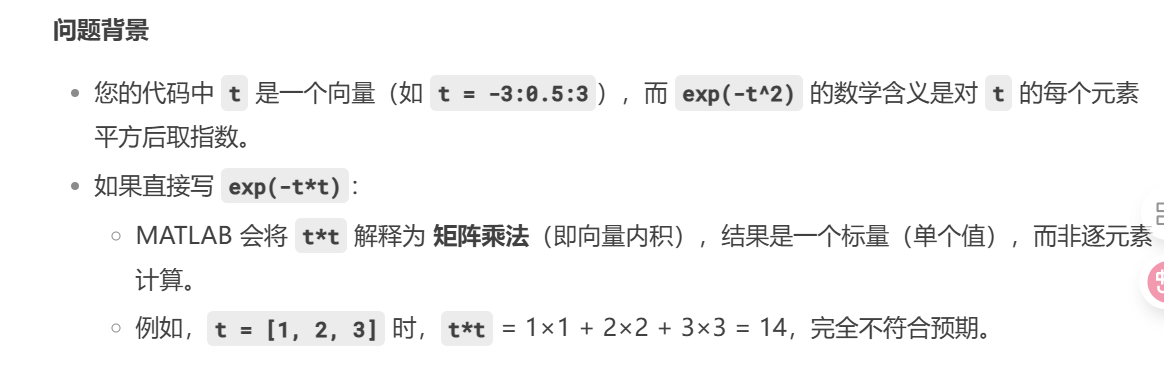

## **3. 极坐标图**

**polarplot函数用来绘制极坐标图**

theta = 0:0.01:2*pi ;                    %2*pi表示2Π
radi = abs(sin(7*theta).*cos(10*theta) ) %abs表示取绝对值 .*表示纯粹数学意义上的计算

radi =          0    0.0696    0.1368    0.1991    0.2545    0.3009    0.3365    0.3600    0.3701    0.3662    0.3481    0.3158    0.2698    0.2112    0.1412    0.0614    0.0263    0.1196    0.2163    0.3140    0.4101    0.5023    0.5882    0.6658    0.7330    0.7883    0.8304    0.8584    0.8718    0.8704    0.8546    0.8251    0.7830    0.7298    0.6672    0.5972    0.5222    0.4444    0.3664    0.2904    0.2190    0.1542    0.0982    0.0526    0.0189    0.0018    0.0088    0.0018    0.0190    0.0530


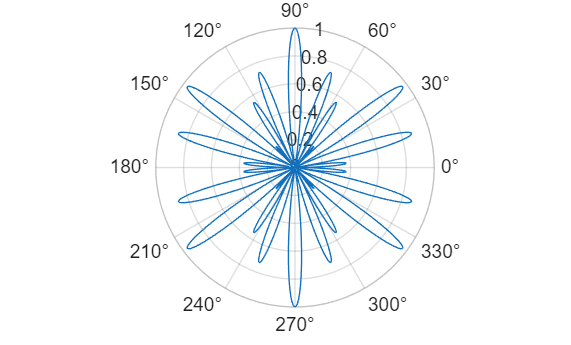

polarplot(theta,radi)                    %第一个变量-弧度（取值范围），第二个-半径

## **4. 散点图**

**scatter 函数用来绘制x y散点图**

Height = randn(1000,1)  %生成1000x1矩阵，数字随机 符合整体分布

Height =    -0.4913
    0.6577
    1.4361
   -1.5350
    1.7528
    1.2831
    0.0936
    1.5801
    0.2448
   -1.0203
    1.1278
    2.2325
   -0.7742
   -1.0015
    1.1383


Weight = randn(1000,1) 

Weight =    -1.4419
   -0.9601
    0.3476
   -0.1031
    0.6606
    1.1571
   -0.9194
   -0.9705
    0.4561
   -0.1208
    0.0129
   -0.8856
   -0.9486
    0.4468
    1.5601


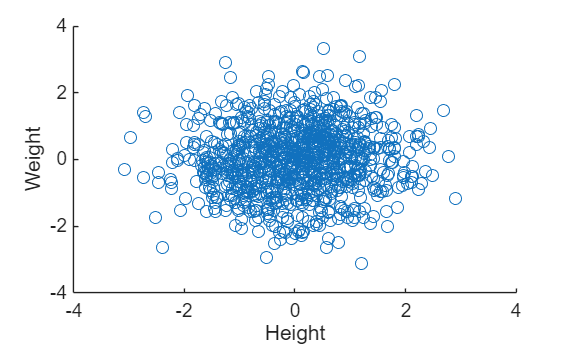

scatter(Height,Weight)
xlabel('Height')
ylabel('Weight')

# **MATLAB三维图和内嵌子图**

## **1.  三维曲面图**

**surf函数可用来做三维曲面图，一般是展示函数 z = z(x,y)的图像**

**首先需要用 meshgrid 创建好空间上 （x,y)点**

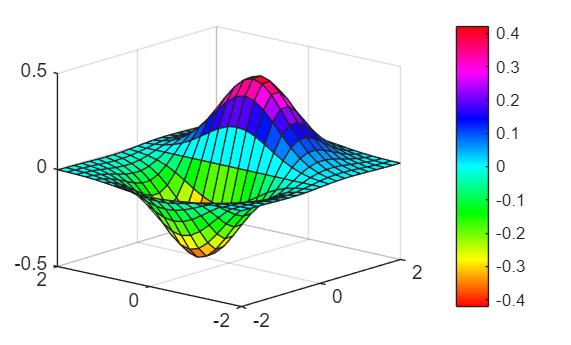

[X,Y] = meshgrid(-2:0.2:2);
%Z = X.^2+Y.^2
Z = X.*exp(-X.^2-Y.^2);
surf(X,Y,Z);

colormap hsv            %colormap设置颜色（winter summer...）hsv是一种颜色模型
colorbar                %会出现数值相对应的颜色色条

## 2. 子图

使用subplot函数可以在同一窗口的不同子区域显示多个绘图

theta = 0:0.01:2*pi ;                   
radi = abs(sin(7*theta).*cos(10*theta) )

radi =          0    0.0696    0.1368    0.1991    0.2545    0.3009    0.3365    0.3600    0.3701    0.3662    0.3481    0.3158    0.2698    0.2112    0.1412    0.0614    0.0263    0.1196    0.2163    0.3140    0.4101    0.5023    0.5882    0.6658    0.7330    0.7883    0.8304    0.8584    0.8718    0.8704    0.8546    0.8251    0.7830    0.7298    0.6672    0.5972    0.5222    0.4444    0.3664    0.2904    0.2190    0.1542    0.0982    0.0526    0.0189    0.0018    0.0088    0.0018    0.0190    0.0530


Height = randn(1000,1)  

Height =    -0.6455
   -0.2891
    1.0004
   -0.5881
    1.5575
   -1.3614
    1.9001
    0.1779
   -2.1666
    0.7069
   -2.2253
    0.3412
    2.2512
   -0.1661
    0.4870


Weight = randn(1000,1)

Weight =    -1.0501
    0.4687
    0.2829
    1.3412
    0.3806
    1.4354
    0.7996
    1.6286
    0.1291
   -2.0848
   -0.6471
   -0.2517
    0.1902
   -0.4675
    0.5307


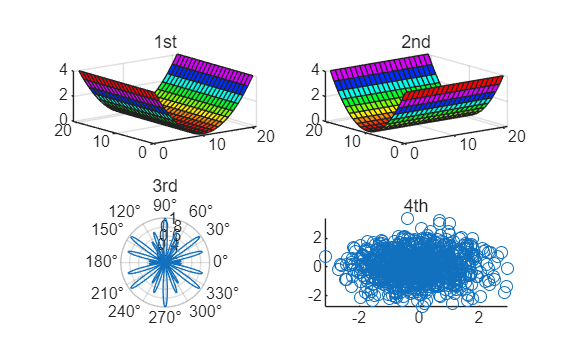


%(2,2,1)；代表两行两列，放四个图，这是第一张
subplot(2,2,1); surf(X.^2);title('1st')
subplot(2,2,2); surf(Y.^2);title('2nd')
subplot(2,2,3); polarplot(theta,radi);title('3rd')
subplot(2,2,4); scatter(Height,Weight);title('4th')

# **MATLAB导入数据及注意事项**

最常用的是导入excel，主页-导入数据

**1. 导入范围**

- **默认从第二行开始，第一行为标题行**

- **左上角空白按住为全选**

- **ctrl按住再点索引or列   可以取消也可以勾上**

- **A代表从那开始，BK代表在那结束**

- **matlab最上面会显示变量，一般默认为原文件第一行，只认识英文**

**2. 导入类型**

- **输出类型决定导入的数据以什么类型存储**

       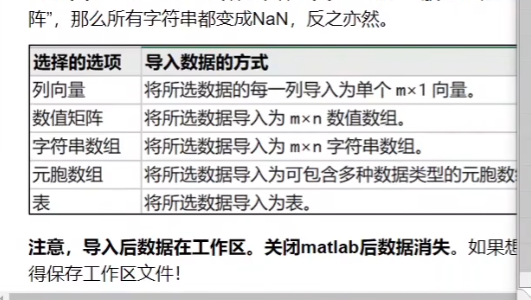一般是导入为表（啥类型都能导入

列向量会变为很多个以列名为名的表格，数值矩阵除了数字全是NaN（可筛选出单数值表）

以上三个最常用

**3. 处理无法导入数据**

- **替换/排除行or列**

# **MATLAB处理缺失值和异常值**

**清理缺失数**

**实施编辑器-任务-清理确实很数据**

险些一组包含缺失值和异常值的例子

x = 1:100;  %构造一个数组，元素为1，2，3，......，100
%randn(1,100)意味着生成一个1x100的矩阵
%矩阵元素均值为0，方差σ^2 = 1，且符合正态分布的随机数
deta = randn(1,100)

deta =     0.1549   -1.3068    1.5257    0.9586   -0.9862   -0.2372   -0.4858   -0.0612   -0.6399   -0.7153    0.1814   -0.3026   -0.0022   -0.3515   -0.1449    0.2141   -0.6541    1.3856    0.6051   -2.7554   -0.6627    0.6439    0.9357   -1.4265    1.7664   -0.0398   -1.5026   -0.4250   -0.6493    1.5705   -2.1910   -0.8071    0.3868    0.7429   -1.6248    1.3680   -1.4088   -0.8822   -0.3466    0.8428    0.5507    0.0051    0.8773   -0.5435    1.5722    0.0919   -1.8416   -0.9041   -0.9856   -1.1298


deta(20:20:80) = NaN

deta =     0.1549   -1.3068    1.5257    0.9586   -0.9862   -0.2372   -0.4858   -0.0612   -0.6399   -0.7153    0.1814   -0.3026   -0.0022   -0.3515   -0.1449    0.2141   -0.6541    1.3856    0.6051       NaN   -0.6627    0.6439    0.9357   -1.4265    1.7664   -0.0398   -1.5026   -0.4250   -0.6493    1.5705   -2.1910   -0.8071    0.3868    0.7429   -1.6248    1.3680   -1.4088   -0.8822   -0.3466       NaN    0.5507    0.0051    0.8773   -0.5435    1.5722    0.0919   -1.8416   -0.9041   -0.9856   -1.1298


%设置4个缺失值
deta(10) = -50

deta =     0.1549   -1.3068    1.5257    0.9586   -0.9862   -0.2372   -0.4858   -0.0612   -0.6399  -50.0000    0.1814   -0.3026   -0.0022   -0.3515   -0.1449    0.2141   -0.6541    1.3856    0.6051       NaN   -0.6627    0.6439    0.9357   -1.4265    1.7664   -0.0398   -1.5026   -0.4250   -0.6493    1.5705   -2.1910   -0.8071    0.3868    0.7429   -1.6248    1.3680   -1.4088   -0.8822   -0.3466       NaN    0.5507    0.0051    0.8773   -0.5435    1.5722    0.0919   -1.8416   -0.9041   -0.9856   -1.1298


deta(40) = 45

deta =     0.1549   -1.3068    1.5257    0.9586   -0.9862   -0.2372   -0.4858   -0.0612   -0.6399  -50.0000    0.1814   -0.3026   -0.0022   -0.3515   -0.1449    0.2141   -0.6541    1.3856    0.6051       NaN   -0.6627    0.6439    0.9357   -1.4265    1.7664   -0.0398   -1.5026   -0.4250   -0.6493    1.5705   -2.1910   -0.8071    0.3868    0.7429   -1.6248    1.3680   -1.4088   -0.8822   -0.3466   45.0000    0.5507    0.0051    0.8773   -0.5435    1.5722    0.0919   -1.8416   -0.9041   -0.9856   -1.1298


deta(70) = -40

deta =     0.1549   -1.3068    1.5257    0.9586   -0.9862   -0.2372   -0.4858   -0.0612   -0.6399  -50.0000    0.1814   -0.3026   -0.0022   -0.3515   -0.1449    0.2141   -0.6541    1.3856    0.6051       NaN   -0.6627    0.6439    0.9357   -1.4265    1.7664   -0.0398   -1.5026   -0.4250   -0.6493    1.5705   -2.1910   -0.8071    0.3868    0.7429   -1.6248    1.3680   -1.4088   -0.8822   -0.3466   45.0000    0.5507    0.0051    0.8773   -0.5435    1.5722    0.0919   -1.8416   -0.9041   -0.9856   -1.1298


deta(90) = 50

deta =     0.1549   -1.3068    1.5257    0.9586   -0.9862   -0.2372   -0.4858   -0.0612   -0.6399  -50.0000    0.1814   -0.3026   -0.0022   -0.3515   -0.1449    0.2141   -0.6541    1.3856    0.6051       NaN   -0.6627    0.6439    0.9357   -1.4265    1.7664   -0.0398   -1.5026   -0.4250   -0.6493    1.5705   -2.1910   -0.8071    0.3868    0.7429   -1.6248    1.3680   -1.4088   -0.8822   -0.3466   45.0000    0.5507    0.0051    0.8773   -0.5435    1.5722    0.0919   -1.8416   -0.9041   -0.9856   -1.1298


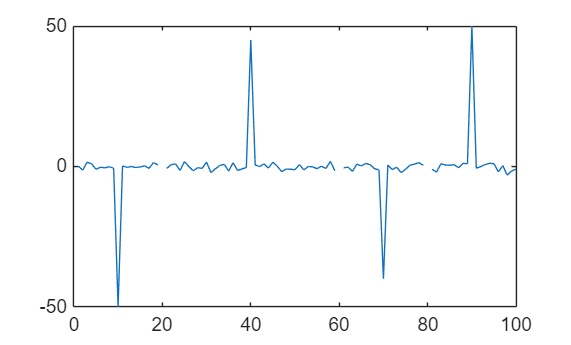

plot(x,deta)

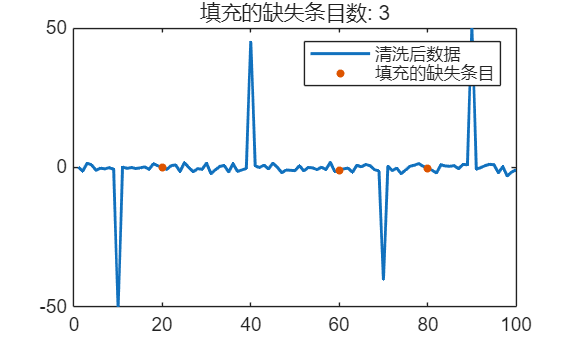

% 填充缺失数据
[cleanedData,missingIndices2] = fillmissing(deta,"linear");

% 显示结果
figure

% 绘制清洗后的数据
plot(cleanedData,SeriesIndex=1,LineWidth=1.5,DisplayName="清洗后数据")
hold on

% 绘制填充的缺失条目
plot(find(missingIndices2),cleanedData(missingIndices2),".",MarkerSize=12, ...
    SeriesIndex=2,DisplayName="填充的缺失条目")
title("填充的缺失条目数: " + nnz(missingIndices2))

hold off
legend

clear missingIndices2


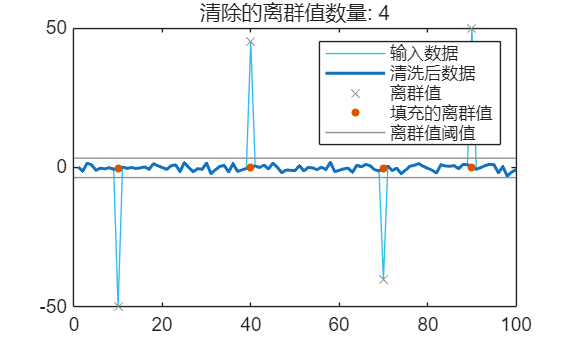

% 填充离群值
[cleanedData2,outlierIndices,lo,hi] = filloutliers(cleanedData,"linear");

% 显示结果
figure
plot(cleanedData,SeriesIndex=6,DisplayName="输入数据")
hold on
plot(cleanedData2,SeriesIndex=1,LineWidth=1.5,DisplayName="清洗后数据")

% 绘制离群值
plot(find(outlierIndices),cleanedData(outlierIndices),"x", ...
    Color=[145 145 145]/255,DisplayName="离群值")

% 绘制填充的离群值
plot(find(outlierIndices),cleanedData2(outlierIndices),".",MarkerSize=12, ...
    SeriesIndex=2,DisplayName="填充的离群值")

% 绘制离群值阈值
plot([xlim missing xlim],[lo lo missing hi hi],Color=[145 145 145]/255, ...
    DisplayName="离群值阈值")

hold off
title("清除的离群值数量: " + nnz(outlierIndices))
legend

clear lo hi

记得输入数据为CleanedData（在之前填补缺失值的基础上再次清洗）

检测方法一般用中位数和均值